## COVID-19 in BC

**Objective: **To fit the two-age group *SI(R)I(UR)R *model of COVID-19 transmission to the reported case data under various constraints.

## Initialization 

clear all; clc;

%% Select region, timeframe, age-cutoff
region = 'BC';
start_date = 'Aug 01, 2020';
end_date = 'Oct 31, 2020';
age_cutoff = 60;
Month = 'Sept';

%% Set parameters
D_T = 5.0;
D = [D_T, D_T]; % Mean infectious period for an I in Group i
T_T = 0.25;
T = [T_T,T_T]; % Ascertainment fraction of I in Group i 
N = pop_two_groups(age_cutoff); % Estimate for population of Group i 
tspan = 1:1:(datenum(end_date)-datenum(start_date)+1); % timespan over which ODE solved

%% Import data and format to yield cumulative reported cases and initial active cases
dataI = readtable('pathway.csv'); % replace with pathway of file storing cumulative reported case data
observedI = data_selection_two_groups(dataI, start_date, end_date);
% y1 = init_cond_two_groups(dataI, start_date, D_T, N, T);

## Optimization: fmincon

%% Set transmission parameter constraint (must do so in pred_cases_two_groups.m file)
para0 = [0.5,0.1];

%% Calculate theoretical epidemic and residual sum of squares
predicted = @(para) pred_cases_two_groups_survey60(D, N, para, tspan, Month, dataI, start_date);
% min_fun = @(para) sum_squares_two_groups(predicted(para), observedI, tspan);
min_fun = @(para) sum_squares_two_groups_norm(predicted(para), observedI, tspan);

%% Optimize parameter given constraint
A = [];
b = [];
Aeq = [];
beq = [];
lb = [0,0];
ub = [1,1];


para_opt = fmincon(min_fun, para0,A,b,Aeq,beq,lb,ub)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


para_opt =     0.0521    0.0147


error_value = min_fun(para_opt)

error_value = 0.1480

graph_min = function_handle with value:
    @(b)min_fun([b,0.01])


large =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


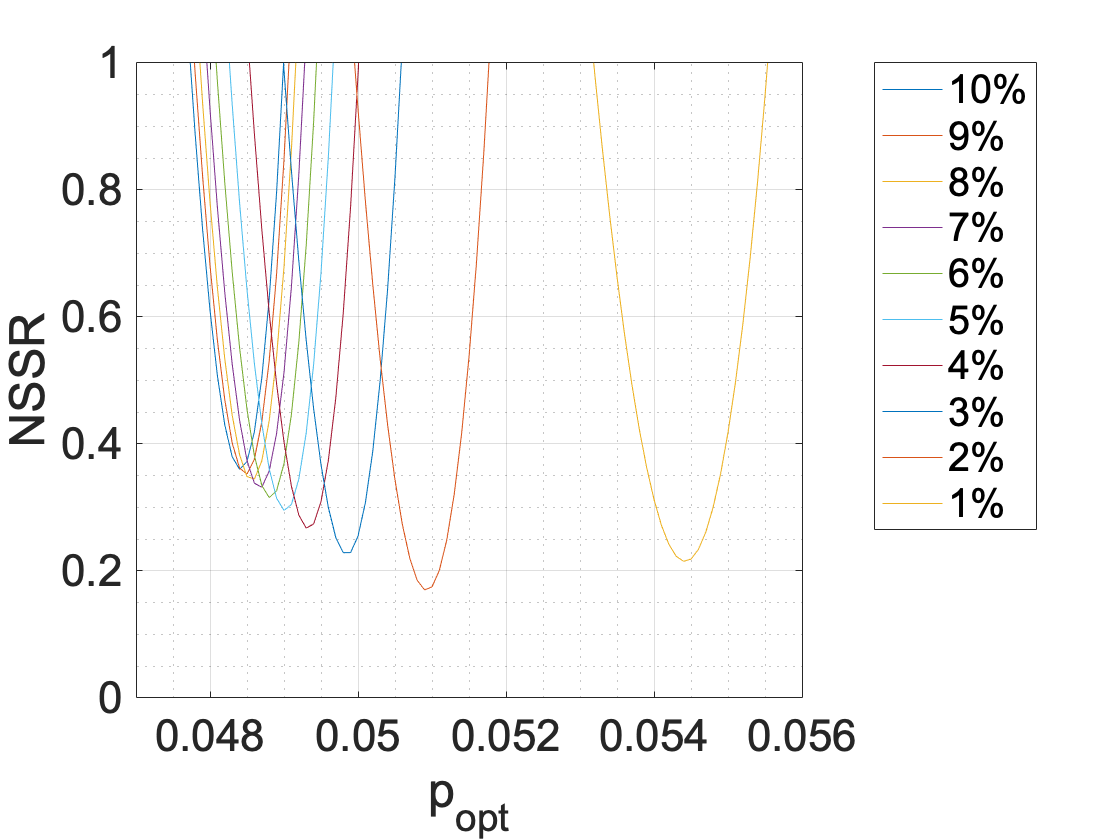

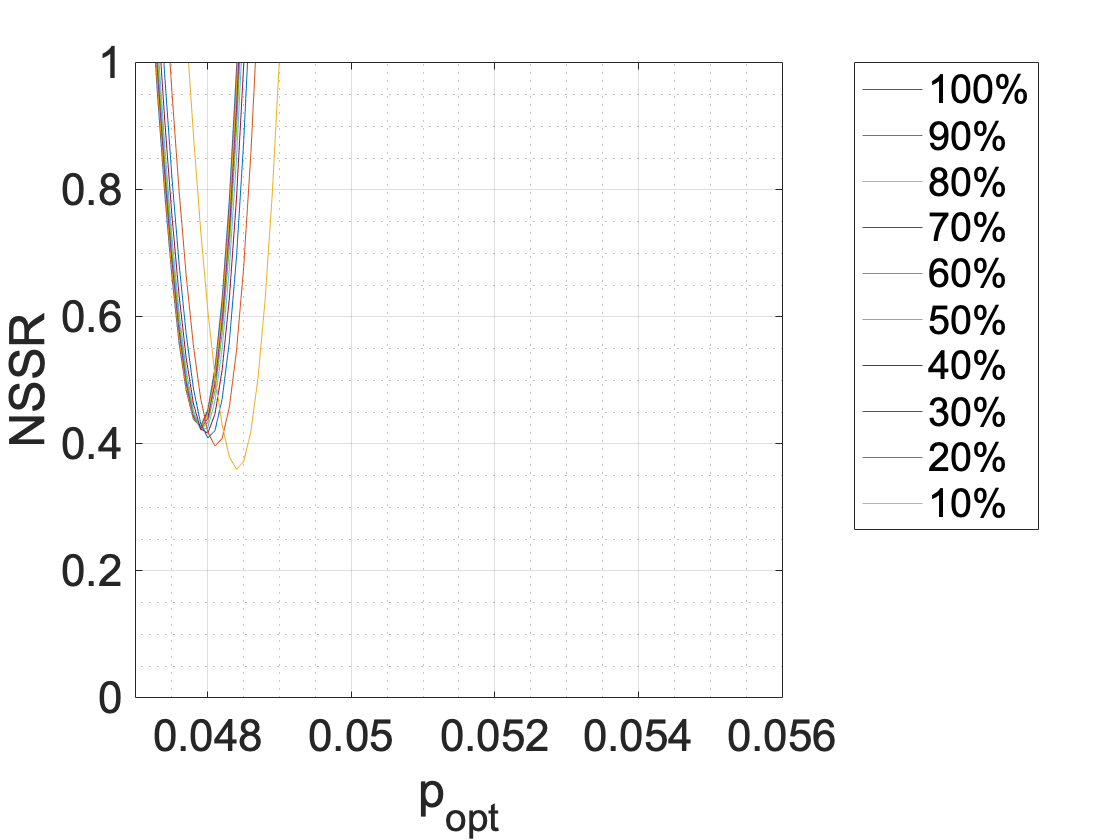


% Specify which survey data to use as constraint
if strcmp(Month,'May')
    beta_opt = para_opt(1).*[2.178040541, 0.386036036; 1.235465587, 0.959878543];
elseif strcmp(Month,'July')
    beta_opt = para_opt(1).*[1.912062257, 0.341984436; 1.067804878, 0.958414634];
elseif strcmp(Month,'Sept')
    beta_opt = para_opt(1).*[4.44574359, 0.506615385; 1.399338843, 0.738677686];
elseif strcmp(Month,'Dec')
    beta_opt = para_opt(1).*[2.768723404, 0.602234043; 1.661165049, 0.783300971];
end

## Plotting

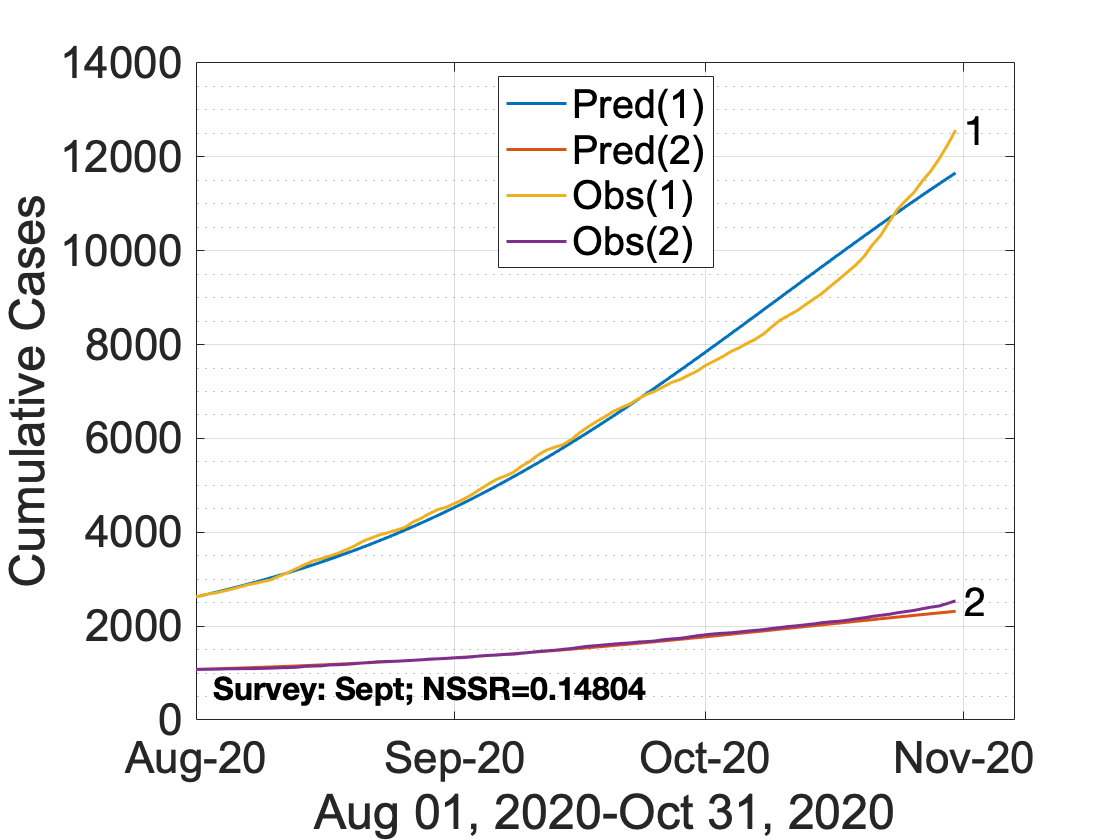

% Plot predicted cases against observed cases 

obsI = observedI;
pred = predicted(para_opt);


for i = tspan
    graphI (i,1) = pred(i,1);
    graphI (i,2) = pred(i,2);
    graphI (i,3) = obsI(i,1);
    graphI (i,4) = obsI(i,2);
end

date_vector = transpose(datetime(start_date):datetime(end_date));

plot(date_vector,graphI,'LineWidth', 1.5, 'MarkerSize', 18)
legend('Pred(1)','Pred(2)','Obs(1)', 'Obs(2)', 'Location', 'Best')
xlabel(strcat(start_date,'-', end_date))
ylabel('Cumulative Cases')
% title(strcat(region, ': 0-', string(age_cutoff), ',', string(age_cutoff), '+'))
xtickformat('MMM-yy')
grid on;
grid minor;
set(gca, 'FontSize', 22)
set(gca, 'FontName', 'Arial')
text(tspan(length(tspan)), graphI (tspan(length(tspan)),3), '1', "FontSize",20)
text(tspan(length(tspan)), graphI (tspan(length(tspan)),4), '2', "FontSize",20)

plot_text = strcat('Survey:', {' '}, Month, '; NSSR=', string(error_value));
text(0.02,0.05, plot_text,'Units','normalized', 'FontSize',16, 'FontWeight','bold')